## An implementation of offset-free MPC for temperature tracking using a simple linear plasma model

created with influences from code by Joel A. Paulson

(c) Kimberly J. Chan, Mesbah Lab 2022

close all; clear; clc;

## add package paths

when running this Live Script, make sure you are in the main project directory (not in the directory of this script)!!

addpath(genpath('./config'), genpath('./utils'))

## user inputs

economic_flag = false;  % economic objective flag (CEM setpoint tracking for plasma case studies)
robust_flag = false;    % robust MPC implementation flag (multistage MPC)
offset_flag = true;     % offset-free MPC (reference tracking)
save_file = [];     % filename to save data for future use; leave empty if no save is desired
font_size = 15;     % font size for plotting
line_width = 3;     % line width for plotting

## load problem data

prob_info = offsetfree_load_problem_info();

Linear Model to be used for CONTROL:
A: 
    0.9027    0.0175
    0.1316    0.2426

B: 
    0.5815   -0.2204
    2.6737   -1.1310

C: 
     1     0
     0     1

xss: 
   33.3060
    7.7358

Linear Model to be used for the PLANT:
A: 
    0.8875    0.0546
    0.0935    0.2827

B: 
    0.5028   -0.1740
    2.7637   -1.0366

C: 
     1     0
     0     1

xss: 
   33.3060    7.7358



## set up controller

c = OffsetFreeMPC(prob_info);
c = c.get_mpc();
[c, res, feas] = c.solve_mpc(); % do test run

## initialize simulation

Nsim = ceil(5*60/0.5);
sim = Simulation(Nsim, prob_info);
% run simulation
[sim, sim_data] = sim.run_closed_loop(c, [], [], economic_flag, robust_flag, offset_flag);

Using a MPC.
Using user-provided plant...


disp('sim_data fields:')

sim_data fields:


disp(fieldnames(sim_data))

    {'Xsim'   }
    {'Ysim'   }
    {'Usim'   }
    {'Jsim'   }
    {'Yrefsim'}
    {'ctime'  }
    {'Xhat'   }
    {'Ypred'  }
    {'Xss_sim'}
    {'Uss_sim'}
    {'Yss_sim'}



## plot data

ctime = sim_data.ctime;
fprintf('Total Runtime: %.2f s\n', sum(ctime))

Total Runtime: 10.15 s


fprintf('Average Runtime: %.4f s\n', mean(ctime))

Average Runtime: 0.0169 s


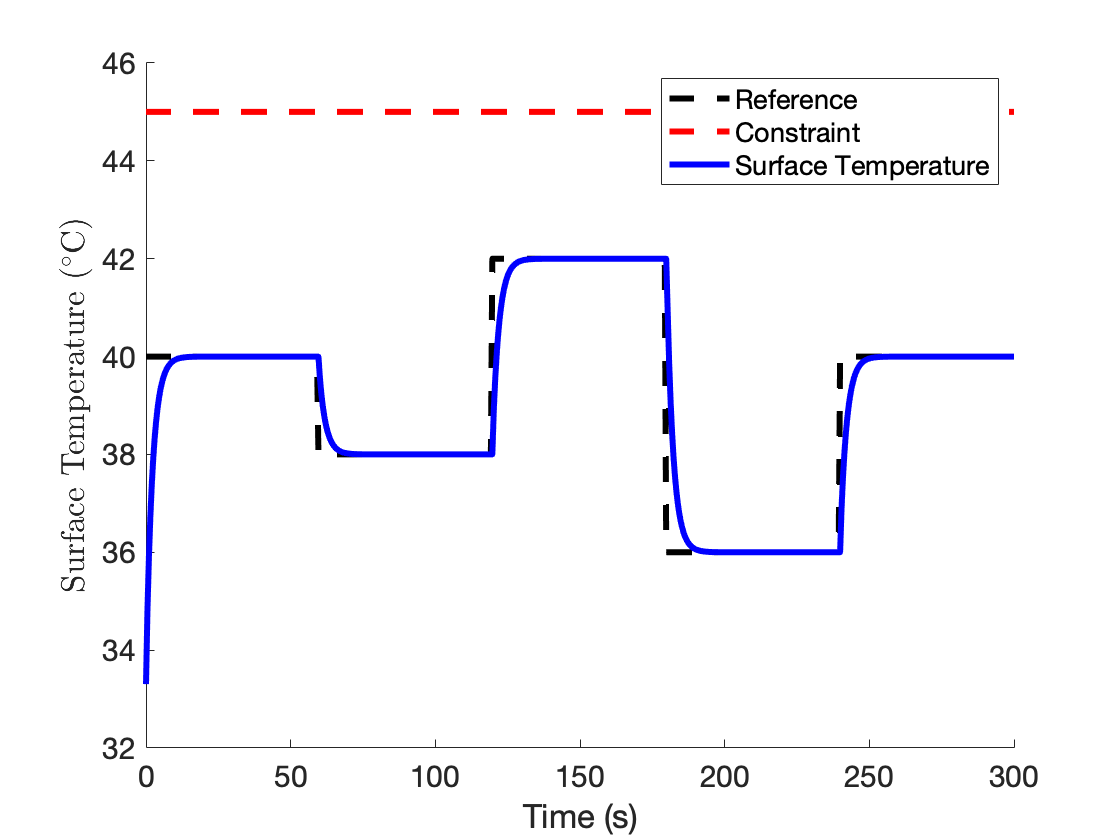


sim_ref = sim_data.Yrefsim + prob_info.xss(1); % reference was saved as deviation variable using the PREDICTION model as basis
Tplot = sim_data.Xsim(1,1:end-1) + prob_info.xssp(1); % states are taken as deviation variables using the PLANT model as basis
t = linspace(0,length(sim_ref),length(sim_ref))*prob_info.ts;

figure()
subplot(111)
hold on
plot(t, sim_ref, 'k--', 'LineWidth', line_width, 'DisplayName', 'Reference')
T_max = (prob_info.x_max(1)+prob_info.xss(1))*ones(size(Tplot));
plot(t, T_max, 'r--', 'LineWidth', line_width, 'DisplayName', 'Constraint')
plot(t, Tplot, 'b-', 'LineWidth', line_width, 'DisplayName', 'Surface Temperature')
xlabel('Time (s)')
ylabel('Surface Temperature ($^\circ$C)', 'Interpreter', 'latex')
legend()
set(gca, 'Fontsize', font_size)

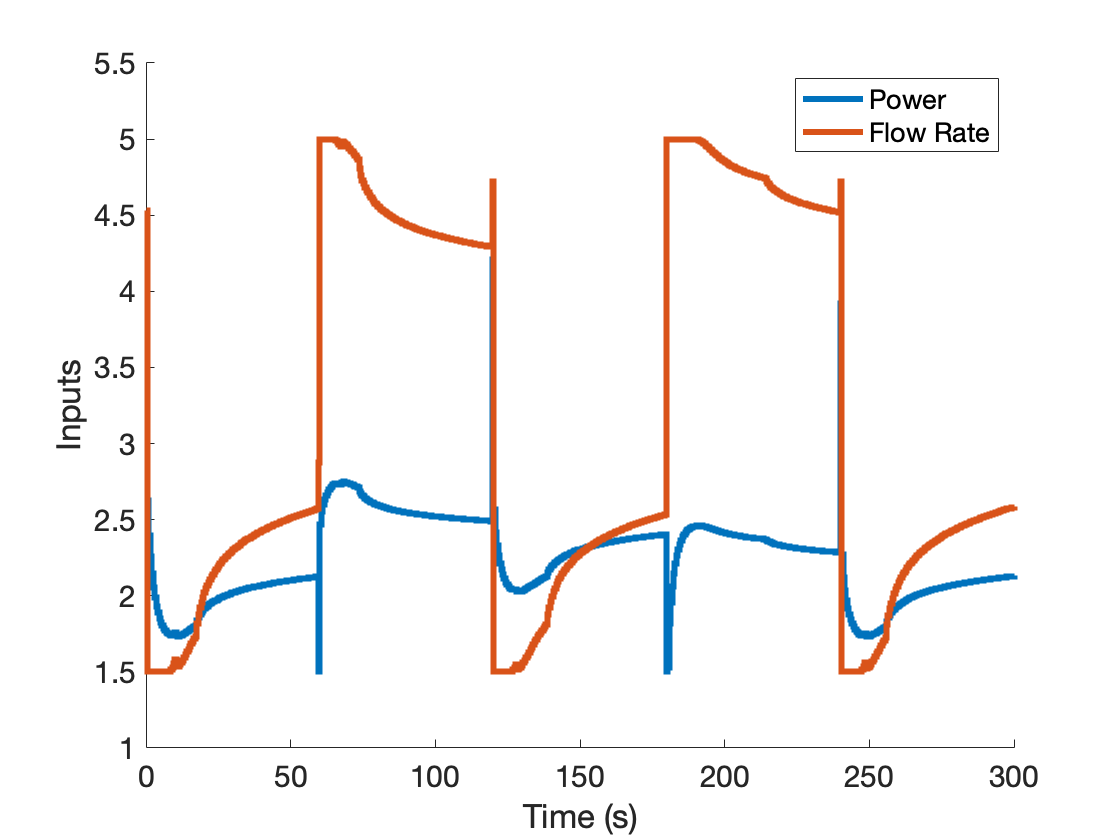


figure()
subplot(111)
hold on
labels = {'Power', 'Flow Rate'};
for i = 1:length(labels)
    u_plot = sim_data.Usim(i,:)+prob_info.ussp(i);
    stairs(t, u_plot, '-', 'LineWidth', line_width, 'DisplayName', labels{i})
end
xlabel('Time (s)')
ylabel('Inputs')
legend()
set(gca, 'Fontsize', font_size)

## save data

if ~isempty(save_file)
    save(save_file, 'sim_data', 'prob_info')
end

## remove package paths

rmpath(genpath('./config'), genpath('./utils'))